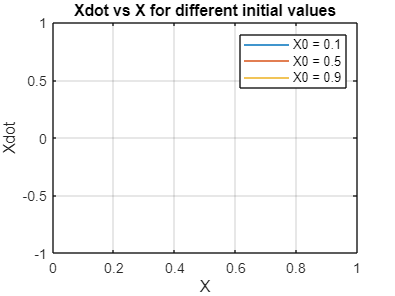


% Initial values
X0_list = [0.1, 0.5, 0.9];

% Plot Xdot vs X for different initial values
for X0 = 1:length(X0_list)
    % Define time range
    tspan = linspace(0, 5, 1000);

    % Solve the differential equation using ODE45
    [T, X] = ode45(@(t, x) gompertz(t, x, 1, 1), tspan, X0);

    % Rescale variables
    [X_rescaled, T_rescaled] = rescale(X, T, 1, 1);

    % Plot
    plot(X_rescaled, f(X), 'DisplayName', ['X0 = ', num2str(X0_list(X0))]);
    hold on;
end

% Label and show the plot
xlabel('X');
ylabel('Xdot');
title('Xdot vs X for different initial values');
legend();
grid on;
hold off;
xlim([0 1]);

% Define the Gompertz equation

function dxdt = gompertz(t, x, a, b)
    dxdt = -a .* log(b .* x);
end

% Rescale variables
function [X, T] = rescale(x, t, a, b)
    X = x / b^(-1); % Corrected power operator
    T = a * t;
end

% Define the parameter-free differential equation
function dXdt = f(X)
    dXdt = -X .* log(X);
end
